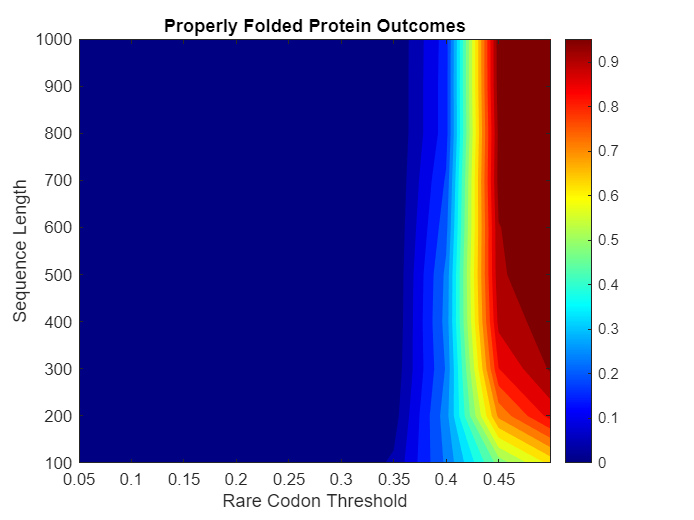

% Simulation for Codon Usage and Folding Outcomes

% Define codon probabilities
codon_probs = struct( ...
    'AAA', 0.008655332302936622, 'AAU', 0.008655332302936622, 'AAG', 0.008655332302936622, 'AAC', 0.023080886141164325, ...
    'AUA', 0.008655332302936622, 'AUU', 0.008655332302936622, 'AUG', 0.010819165378670777, 'AUC', 0.023080886141164325, ...
    'AGA', 0.008655332302936622, 'AGU', 0.008655332302936622, 'AGG', 0.008655332302936622, 'AGC', 0.008655332302936622, ...
    'ACA', 0.008655332302936622, 'ACU', 0.008655332302936622, 'ACG', 0.008655332302936622, 'ACC', 0.023080886141164325, ...
    'UAA', 0.09891808346213285, 'UAU', 0.008655332302936622, 'UAG', 0.09891808346213285, 'UAC', 0.008655332302936622, ...
    'UUA', 0.008655332302936622, 'UUU', 0.023080886141164325, 'UUG', 0.008655332302936622, 'UUC', 0.008655332302936622, ...
    'UGA', 0.09891808346213285, 'UGU', 0.008655332302936622, 'UGG', 0.023080886141164325, 'UGC', 0.008655332302936622, ...
    'UCA', 0.008655332302936622, 'UCU', 0.008655332302936622, 'UCG', 0.008655332302936622, 'UCC', 0.008655332302936622, ...
    'GAA', 0.008655332302936622, 'GAU', 0.023080886141164325, 'GAG', 0.008655332302936622, 'GAC', 0.008655332302936622, ...
    'GUA', 0.008655332302936622, 'GUU', 0.008655332302936622, 'GUG', 0.008655332302936622, 'GUC', 0.008655332302936622, ...
    'GGA', 0.008655332302936622, 'GGU', 0.023080886141164325, 'GGG', 0.008655332302936622, 'GGC', 0.023080886141164325, ...
    'GCA', 0.008655332302936622, 'GCU', 0.008655332302936622, 'GCG', 0.008655332302936622, 'GCC', 0.008655332302936622, ...
    'CAA', 0.023080886141164325, 'CAU', 0.008655332302936622, 'CAG', 0.023080886141164325, 'CAC', 0.008655332302936622, ...
    'CUA', 0.008655332302936622, 'CUU', 0.008655332302936622, 'CUG', 0.023080886141164325, 'CUC', 0.008655332302936622, ...
    'CGA', 0.008655332302936622, 'CGU', 0.008655332302936622, 'CGG', 0.008655332302936622, 'CGC', 0.008655332302936622, ...
    'CCA', 0.008655332302936622, 'CCU', 0.023080886141164325, 'CCG', 0.008655332302936622, 'CCC', 0.008655332302936622 ...
);

% Normalize codon probabilities
total_prob = sum(struct2array(codon_probs));
codon_fields = fieldnames(codon_probs);
for i = 1:numel(codon_fields)
    codon_probs.(codon_fields{i}) = codon_probs.(codon_fields{i}) / total_prob;
end

% Simulation parameters
seq_lengths = 100:100:1000;       % Range of sequence lengths
rare_thresholds = 0.05:0.05:0.5;  % Rare codon thresholds (fraction)

% Initialize results matrix
results = zeros(length(seq_lengths), length(rare_thresholds));

% Codon keys and probabilities
codon_keys = codon_fields;
codon_values = cell2mat(struct2cell(codon_probs));

% Key codons
start_codon = 'AUG';
stop_codons = {'UAA', 'UAG', 'UGA'};
rare_threshold_value = 0.01; % Define rare codons based on this threshold

% Identify rare codons
rare_codons = codon_keys(codon_values < rare_threshold_value);

% Simulation loop
for i = 1:length(seq_lengths)
    for j = 1:length(rare_thresholds)
        % Parameters for this iteration
        seq_length = seq_lengths(i);
        rare_threshold = rare_thresholds(j);
        num_sequences = 1000; % Number of sequences to simulate
        
        properly_folded = 0;
        
        for k = 1:num_sequences
            % Generate random sequence
            sequence = datasample(codon_keys, seq_length, 'Weights', codon_values);
            
            % Analyze sequence
            has_start = any(strcmp(sequence, start_codon));
            has_stop = any(ismember(sequence, stop_codons));
            
            if ~has_start || ~has_stop
                continue;
            end
            
            % Count rare codons
            rare_count = sum(ismember(sequence, rare_codons));
            if rare_count / seq_length < rare_threshold
                properly_folded = properly_folded + 1;
            end
        end
        
        % Store result (percentage of properly folded proteins)
        results(i, j) = properly_folded / num_sequences;
    end
end

% Generate 2D contour plot
figure;
contourf(rare_thresholds, seq_lengths, results, 20, 'LineColor', 'none');
xlabel('Rare Codon Threshold');
ylabel('Sequence Length');
title('Properly Folded Protein Outcomes');
colorbar;
colormap jet;